# A step-by-step guide to parsimoneous enzyme usage Flux Balance Analysis - pFBA

**Author(s): Francisco José Pardo Palacios, Ines Thiele, LCSB, University of Luxembourg.**

**Reviewer(s): Sebastián Mendoza (Center for Mathematical Modeling)**

## INTRODUCTION

In this tutorial, we show how the calculations described in Lewis et al. (2010) [1] have been implemented in Matlab ('pFBA.m'), which is available in the COBRA toolbox.

The main idea of this tutorial is to explain how the calculations are done in order to understand the pFBA analysis and be able to classify, under certain conditions, the genes of a modelEcore as: essential, pFBA optima, Enzymatically Less Efficient (ELE), Metabolically Less Efficient (MLE) or pFBA no-flux genes. 

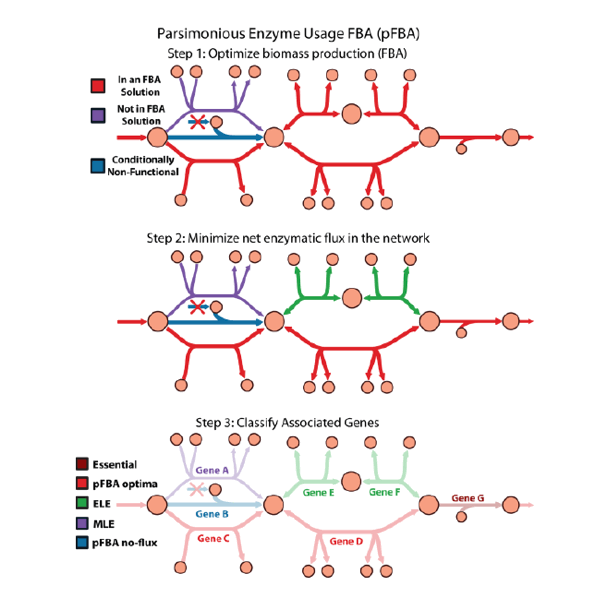

                                       Figure: Gene/enzyme classification scheme used by pFBA

The results obtained could then be compared to data from evolved E. coli and observe if the modelEcore can predict that evolution.

In order to do it, all the steps described in the pFBA flowchart were implemented and explained in this tutorial. 

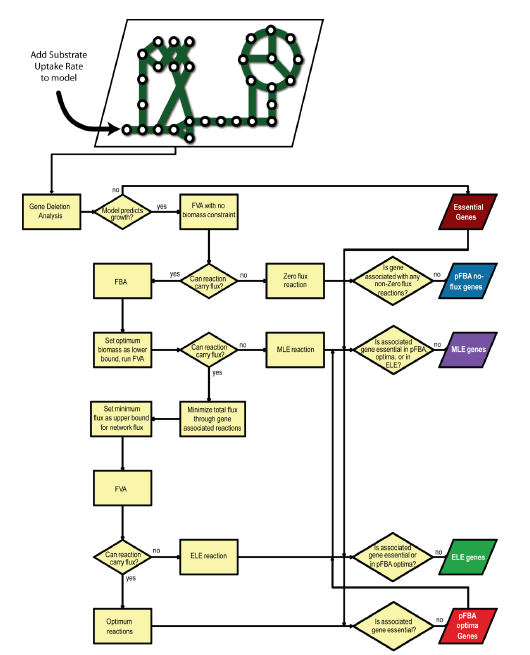

                                                             Figure: pFBA flowchart

## EQUIPMENT SETUP

First of all, the modelEcore needs be loaded, the COBRA solver set and define the uptake of nutrients by the modelEcore. In this case, the modelEcore used will be the E. coli core modelEcore and the substrate used will be glucose, limiting its uptake up to 18 mmol/(gDW·h).

modelEcoreFile='Ecoli_core_model.mat';
load(modelEcoreFile);
changeCobraSolver('glpk');
modelEcore=changeRxnBounds(model,'EX_glc(e)',-18,'l');

## PROCEDURE

The Gene Deletion Analysis is performed. If the modelEcore is not able to predict growth when certain gene is knocked-out,the name of that gene will be saved as essential gene. In order to detect essential genes even if Matlab calculate very small growth,it will be considered as not growing when the growth predict is lower than 0.00001. The rest of the genes will be stored in a non_EG vector.

for i=modelEcore.genes(:,:)
    [grRatio,grRateKO,grRateWT,delRxns,hasEffect]=singleGeneDeletion(modelEcore,'FBA',i);
end

Single gene deletion analysis in progress ...


essential_genes=[];
non_EG=[];
for n=1:length(grRateKO)
    if (grRateKO(n)<0.00001)|(isnan(grRateKO(n))==1)
        essential_genes=[essential_genes;modelEcore.genes(n)];
    else
        non_EG=[non_EG; n];
    end
end

After this, a Flux Variability Analysis (FVA) is performed without any biomass constraint. For that, the percentage of optimal solution should be set to 0. The reactions that do not carry any flux will be stored in a vector called pFBAnoFluxRxn and the rest in the one called pFBAfluxRxn.

[minFluxglc maxFluxglc]=fluxVariability(modelEcore,0);

pFBAnoFluxRxn=[];
pFBAfluxRxn=[];
for i=1:length(modelEcore.rxns)
    if (minFluxglc(i)>-0.00001)&(maxFluxglc(i)<0.00001)    
        pFBAnoFluxRxn=[pFBAnoFluxRxn i];
    else
        pFBAfluxRxn=[pFBAfluxRxn i];
    end
end

Now, it is necessary to know which genes are associated to the reactions not carrying any flux. The information that relates is stored in the rxnGeneMat of the modelEcore. To extract information from it, first it must be converted into a matrix of 0s and 1s. Then, finding that reaction-gene relationships, it is possible to get the names of the genes related with the pFBAnoFluxRxn and create a new vector containing the non essential genes that can actually carry flux (pFBAfluxGenes).

RxnGMat=full(modelEcore.rxnGeneMat);
pFBAfluxGenes=non_EG;
pFBAnoFluxGenes=[];

for i=1:length(pFBAnoFluxRxn)
    listGenes=find(RxnGMat(pFBAnoFluxRxn(i),:));
    for n=1:length(listGenes)
        pos=find(non_EG==listGenes(n));
        if pos 
            pFBAnoFluxGenes=[pFBAnoFluxGenes;modelEcore.genes(non_EG(pos))];
            pFBAfluxGenes(pos)=0;
        end 
    end
end

pFBAnoFluxGenes=unique(pFBAnoFluxGenes);
pFBAfluxGenes(pFBAfluxGenes==0)=[];

As it is suggested by Lewis et al. (2010), a Flux Balance Analysis (FBA) should be calculated and set the optimal growth rate as the lower bound of the biomass production, and then run another FVA. In order to accelerate this process, FVA was directly run, but the percentage of optimal solution was set up to 95%. This means that the minimum and maximum fluxes recorded will be the one that allow at least a 95% of the optimal solution for the objective solution, in this case Biomass production.

The list of reactions carying flux will be scanned and the ones that are "turned off" when the system is forced to achieve certain biomass production will be stored as Metabolically Less Efficient reactions (RxnMLE) and the rest will be saved in a new vector.

[minFlux2 maxFlux2]=fluxVariability(modelEcore,95);

RxnMLE=[];
restRxn=[];
for i=1:length(pFBAfluxRxn)
    if (minFlux2(pFBAfluxRxn(i))>-0.00001)&(maxFlux2(pFBAfluxRxn(i))<0.00001)    
        RxnMLE=[RxnMLE pFBAfluxRxn(i)];
    else
        restRxn=[restRxn pFBAfluxRxn(i)];
    end
end

The next step is to run an FBA, calculate the optimal solution for the biomass production and set it as the lower bound in the modelEcore. Actually, it was set a 95% of the optimal solution because to rigid conditions may not be the best option in some cases.

After that, it was calculated the minimal total flux through the gene associated reactions and those minimal fluxes were set as upper bounds.

FBAsolution=optimizeCbModel(modelEcore,'max');
lowerN=FBAsolution.f*0.95;
modelEcore=changeRxnBounds(modelEcore,'Biomass_Ecoli_core_w_GAM',lowerN,'l');
    
FBAsolution=optimizeCbModel(modelEcore,'min','one');
modelEcore=changeRxnBounds(modelEcore, modelEcore.rxns,FBAsolution.x,'u');

One last FVA was run. The remaining reactions in the restRxn variable are then clasified in Enzymatially Less Eficient Reactions (RxnELE)- if the reactions cannot carry any flux- or Optimal Reactions (RxnOptima)- if they can carry flux.

[minFlux3 maxFlux3]=fluxVariability(modelEcore,100);
tol = 1e-5;
RxnELE=[];
RxnOptima=[];
for i=1:length(restRxn)
    if (minFlux3(restRxn(i))>-tol)&(maxFlux3(restRxn(i))<tol)    
        RxnELE=[RxnELE i];
    else
        RxnOptima=[RxnOptima restRxn(i)];
    end
end
RxnOptima = RxnOptima';
restRxn = restRxn';

The last step is to find again the genes that are related with each reaction. The main point of this is to classify the genes in 5 different grups and store them in different vectors:

***Essential genes:*** metabolic genes necessary for growth in the given media ('essential_genes').

***pFBA optima: ***non-essential genes contributing to the optimal growth rate and minimum gene-associated flux ('OptimaGenes').

***Enzymatically less efficient (ELE): ***genes requiring more flux through enzymatic steps than alternative pathways that meet the same predicted growth rate ('ELEGenes').

***Metabolically less efficient (MLE):*** genes requiring a growth rate reduction if used ('MLEGenes').

***pFBA no-flux:*** genes that are unable to carry flux in the experimental conditions ('pFBAnoFluxGenes').

Some genes may not fit in any of this 5 categories. These genes will be saved in a vetor called 'remainingGenes'.

OptimaGenes=[];
restGenes=pFBAfluxGenes;
for i=1:length(RxnOptima)
    listGenes=find(RxnGMat(RxnOptima(i),:));
    for n=1:length(listGenes)
        pos=find(pFBAfluxGenes==listGenes(n));
        if pos 
            OptimaGenes=[OptimaGenes;modelEcore.genes(pFBAfluxGenes(pos))];
            restGenes(pos,1)=0;
        end 
    end
end
OptimaGenes=unique(OptimaGenes);
restGenes(restGenes==0)=[];    

ELEGenes=[];
restGenes2=restGenes;
for i=1:length(RxnELE)
    listGenes=find(RxnGMat(RxnELE(i),:));
    for n=1:length(listGenes)
        pos=find(restGenes==listGenes(n));
        if pos 
            ELEGenes=[ELEGenes;modelEcore.genes(restGenes(pos))];
            restGenes2(pos,1)=0;
        end 
    end
end
ELEGenes=unique(ELEGenes);
ELEGenes = ELEGenes';
restGenes2(restGenes2==0)=[];

MLEGenes=[];
finalRemainingGenes=restGenes2;
for i=1:length(RxnMLE)
    listGenes=find(RxnGMat(RxnMLE(i),:));
    for n=1:length(listGenes)
        pos=find(restGenes2==listGenes(n));
        if pos 
            MLEGenes=[MLEGenes;modelEcore.genes(restGenes2(pos))];
            finalRemainingGenes(pos,1)=0;
        end 
    end
end
MLEGenes=unique(MLEGenes);
finalRemainingGenes(finalRemainingGenes==0)=[]; 

remainingGenes=[];
for n=1:length(finalRemainingGenes)
        remainingGenes=[remainingGenes ; modelEcore.genes(finalRemainingGenes(n))];
end


- Print results:

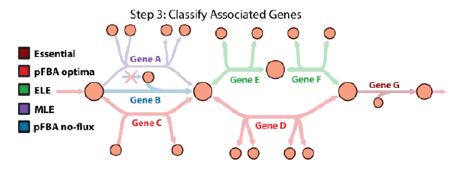

essential_genes'

ans =     'b0720'    'b1136'    'b1779'    'b2415'    'b2416'    'b2779'    'b2926'


OptimaGenes'

ans =     'b0008'    'b0114'    'b0115'    'b0116'    'b0118'    'b0451'    'b0721'    'b0722'    'b0723'    'b0724'    'b0726'    'b0727'    'b0728'    'b0729'    'b0733'    'b0734'    'b0755'    'b0767'    'b0875'    'b0978'    'b0979'    'b1101'    'b1276'    'b1297'    'b1611'    'b1612'    'b1621'    'b1676'    'b1723'    'b1761'    'b1773'    'b1849'    'b1852'    'b1854'    'b2029'    'b2097'    'b2276'    'b2277'    'b2278'    'b2279'    'b2280'    'b2281'    'b2282'    'b2283'    'b2284'    'b2285'    'b2286'    'b2287'    'b2288'    'b2296'    'b2297'    'b2417'    'b2458'    'b2464'    'b2465'    'b2914'    'b2925'    'b2935'    'b2987'    'b3115'    'b3236'    'b3386'    'b3493'    'b3612'    'b3731'    'b3732'    'b3733'    'b3734'    'b3735'    'b3736'    'b3737'    'b3738'    'b3739'    'b3870'    'b3916'    'b3919'    'b3956'    'b4025'    'b4090'    'b4122'    'b4301'    'b4395'    's0001'


ELEGenes

ELEGenes =     'b0351'    'b0356'    'b0474'    'b0485'    'b0902'    'b0903'    'b1241'    'b1478'    'b1479'    'b1524'    'b1812'    'b2579'    'b2587'    'b2975'    'b3114'    'b3212'    'b3213'    'b3403'    'b3603'    'b3951'    'b3952'    'b4015'


MLEGenes'


ans =

  1×0 empty double row vector



pFBAnoFluxGenes'

ans =     'b0809'    'b0810'    'b0811'    'b1817'    'b1818'    'b1819'    'b3528'


## TIMING

The tutorial runs in a few minutes.

## References

[1] Lewis et al. "Omic Data from Evolved Strains are Consistent with Computed Optimal Growth States", Mol Syst Biol, 2010.